## Figure 1

**Run Time**: Seconds

**Requirements: **thresholdfun.m, parameters.m, traj_a_022.csv, traj_a_022.csv, and traj_a_024.csv all need to be in the working directory so that this script can call them

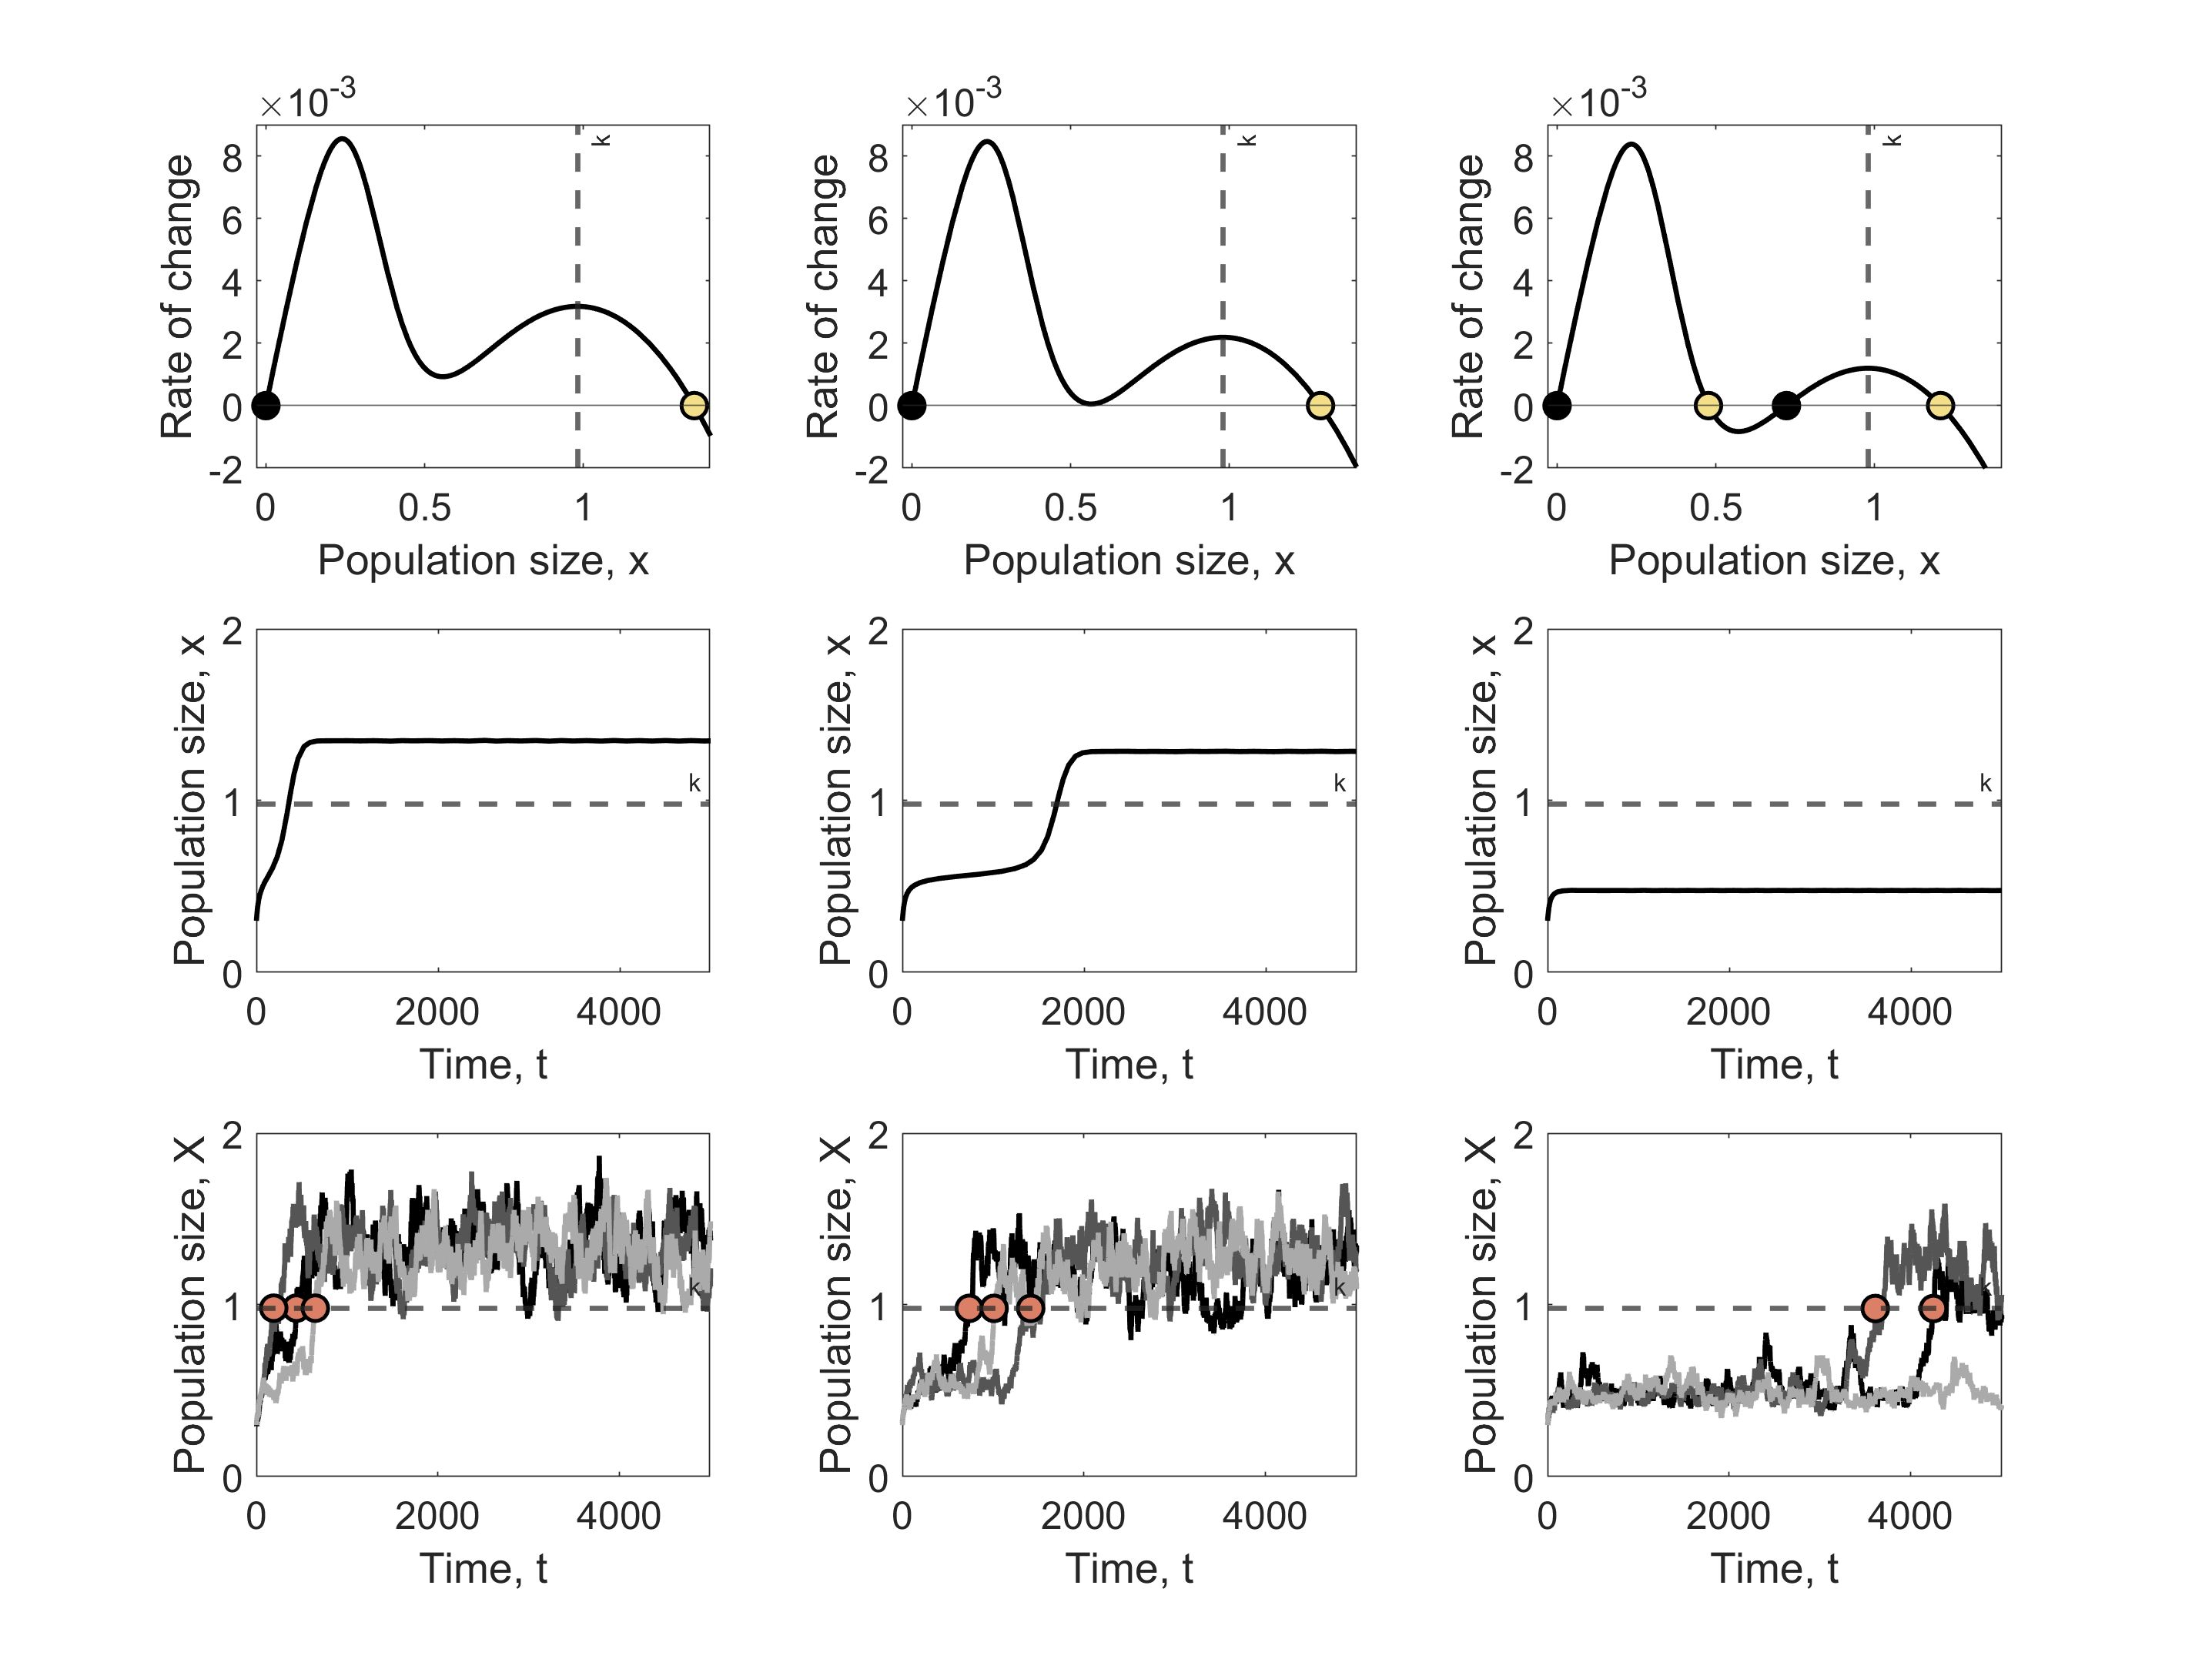

clear;

% define relevant parameters
xinit = 0.3; % initial condition
avals=[0.022 0.023 0.024]; % a value of each column
Tmax=5000; % length of deterministic solutions

% define colors
stableSScol= (1/255)*[243, 222, 138];
FPTcol=(1/255)*[219, 127, 103];

%find FPT threshold for each a value
betas = thresholdfun(avals);

%Make a Tiled Layour
tiledlayout(3,3);

%First row: plot flux function, f(x) 
for j=1:3
    nexttile;
    a=avals(j);
    
    %Parameters
    fplot(@(x) fDE(x,a),[0 1.4],'k','LineWidth',2);
    yline(0);
    xline(betas(j),'--','k','LineWidth',2);
    hold on
    if j==1 || j==2
        %roots=[fzero(@(x) fDE(x,a),0.1) fzero(@(x) fDE(x,a),1.4)];
        root1=fzero(@(x) fDE(x,a),0.1);
        root2=fzero(@(x) fDE(x,a),1.4);
        scatter(root1,0,100,'MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1.5);
        scatter(root2,0,100,'MarkerEdgeColor','k','MarkerFaceColor',stableSScol,'LineWidth',1.5);
    elseif j==3
        roots=[fzero(@(x) fDE(x,a),0.1) fzero(@(x) fDE(x,a),0.4) fzero(@(x) fDE(x,a),0.7) fzero(@(x) fDE(x,a),1.4)];
        root1=fzero(@(x) fDE(x,a),0.1);
        root2=fzero(@(x) fDE(x,a),0.4);
        root3=fzero(@(x) fDE(x,a),0.7);
        root4=fzero(@(x) fDE(x,a),1.4);
        scatter(root1,0,100,'MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1.5);
        scatter(root2,0,100,'MarkerEdgeColor','k','MarkerFaceColor',stableSScol,'LineWidth',1.5);
        scatter(root3,0,100,'MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1.5);
        scatter(root4,0,100,'MarkerEdgeColor','k','MarkerFaceColor',stableSScol,'LineWidth',1.5);
    end
    ylabel("Rate of change","FontSize",20);
    xlabel("Population size, x","FontSize",20);
    xlim([-.03 1.4]);
    ylim([-.002 .009]);
    ax = gca;
    ax.FontSize = 15;
    hold off
end

%Second row: plot deterministic solutions x(t)
for j=1:3
    nexttile;
    a=avals(j);
    [t,y] = ode23(@(t,y) DE(t,y,a), [0 Tmax],xinit);
    plot(t,y,'k','LineWidth',2);
    yline(betas(j),'--','k','LineWidth',2)
    ylabel("Population size, x","FontSize",20);
    xlabel("Time, t","FontSize",20);
    ylim([0 2]);
    xlim([0 Tmax])
    ax = gca;
    ax.FontSize = 15;
end

%Third row: plot stochastic solutions X(t)
fnames=["traj_a_022.csv" "traj_a_023.csv" "traj_a_024.csv"]; % names of csv files containing stochastic trajectories
% trajectories were generated in R using Fit1-StochasticTrajectories.R

colormap('gray')
for j=1:3
    nexttile;
    a=avals(j);
    X=readmatrix(fnames(j));
    plot(X,'LineWidth',2)
    set(gca, 'ColorOrder', colormap(gray(4)))
    hold on
    fpt=zeros(size(X,2),1);
    for l=1:3
        if max(X(:,l))>=betas(1)
            fpt(l)=find(X(:,l)>=betas(1),1,'first');
        else
            fpt(l)=10000; % make it big so not seen in plot
        end
    end
    yline(betas(j),'--','k','LineWidth',2)
    %scatter(fpt,betas(j)*ones(1,length(fpt)),100,FPTcol,'filled');
    scatter(fpt,betas(j)*ones(1,length(fpt)),100,'MarkerEdgeColor','k',...
              'MarkerFaceColor',FPTcol,...
              'LineWidth',1.5);
    
    ylabel("Population size, X","FontSize",20)
    xlabel("Time, t","FontSize",20)
    xlim([0 size(X,1)])
    ylim([0 2])
    ax = gca;
    ax.FontSize = 15;
end

% Prepare and save figure for publication
width = 1200; % Width in pixels
height = 900; % Height in pixels
set(gcf, 'Position', [100, 100, width, height]); % Set figure position and size
exportgraphics(gcf, 'Fig1.pdf', 'BackgroundColor', 'none');

function f = fDE(x,a)

    %Parameters
    [r,K,h,q,~] = parameters();

    f = r*x.*(1-(x/K)) - (a*x.^(q))./(x.^(q) + h^(q));
end

function f = DE(~,x,a)

    %Parameters
    [r,K,h,q,~] = parameters();

    f = r * x * (1-(x/K)) - (a*x^(q))/(x^(q) + h^(q));
end